**EXERCISE 1**

a) **Determine the filter coefficients f0 and f1 of the Daubechies db2 wavelet**. Show that they are the same as the filter coefficients of the Haar wavelet. Indeed: only the conditions (i) and (ii) apply in this case, requirement (iii) is automatically satisfied and requirement (iv) is limited to requirement (ii).

%The conditions are written in the dbfeq.m script which is
% which is then used by dbfilter(n) to output the coefficients
f1 = dbfilter(1)

f1 =     0.5000    0.5000


b) **Determine the filter coefficients f0; f1; f2; f3 of the Daubechies db4 wavelet**. In addition to the conditions (i) and (ii), now also the conditions (iii) and (iv) must hold (with two zeros at z = -1).

f2 = dbfilter(2)

f2 =    -0.0915    0.1585    0.5915    0.3415


c) **Compute the filter coeefficients f0; f1; f2; f3; f4; f5 of the Daubechies db6 wavelet**. Now the requirements (iii) and (iv) each yield two conditions (three zeros of F(z) are to be located at z = -1).

f3 = dbfilter(3)

f3 =     0.2352    0.5706    0.3252   -0.0955   -0.0604    0.0249


d) **Test your software for longer length filters**. As a tool the following function is provided in p-code: function [] = testDbFilter(numIt,tol,Nmax), with optional parameters

**numIt** The number of random trials to do (default=100)

**tol** Tolerance on the error norm (default=1e-3)

**Nmax** Half the maximum filter length (default 10)

%% Just uncomment and run this script in the command and it will test the things. Takes ages.

%testDbFilter

**EXERCISE 2**

**Load the data in the file lab4 dataset1.mat. Use the function discreteWaveletTransform** (but watch out with proper scaling!) to calculate a single step in the Daubechies 4 wavelet transform. This function takes the signal, the low-pass filter (e.g. the filter coefficients f ) and the high-pass filter (alternating flip of f ) as an input and returns the approximation coefficients and detail coefficients.

load("lab4_dataset1.mat");
s1 = s;

[h1,g1] = dbfilter(2)

h1 =    -0.0915    0.1585    0.5915    0.3415


g1 =    -0.3415    0.5915   -0.1585   -0.0915


[a,d] = discreteWaveletTransformCausal(s1,h1,g1);
a.'

ans =          0         0         0   -0.0347    2.3108    5.1392    7.9676   10.7961   13.6245   16.4529   19.2814   22.1445   22.6274   22.6274   22.6274   22.6274   22.6274   22.6274   22.6274   19.5959  -22.6274  -22.6274  -22.6274  -22.6274  -22.6274  -22.6274  -22.6274  -22.6968  -18.0058  -12.3490   -6.6921   -0.9659


d.'

ans =          0         0         0   -0.1294    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1294    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  -11.3137   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.2588   -0.0000   -0.0000   -0.0000    0.2588


b) **Implement the function s = discreteWaveletreconstruction(a,d,Lp r,Hp r) to do the reconstruction and verify that the function is working properly**. This should be easy to test, since you know the original signal before feeding it into discreteWaveletTransform.

s_out = discreteWaveletreconstruction(a,d,h1,g1)

s_out =          0         0         0         0         0         0   -0.0000   -0.0000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000  -16.0000


s1

s1 =      0     0     0     0     0     0     0     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16    16   -16   -16   -16   -16   -16   -16   -16   -16   -16   -16


c)** Calculate four scales in the multiresolution analysis of the dataset**, using a ”logarithmic tree” of Daubechies 4 filter banks. For that, implement the wldecom and wlrecon functions. The output of this function should be an arrayC of the form: C = [approx.coef.(J - j)|detail.coef.(J - j)| ... |detail.coef.(J)]

[h2,g2] = dbfilter(2);
c = wldecom_Db(s1,3,2)

h =    -0.0915    0.1585    0.5915    0.3415


g =    -0.3415    0.5915   -0.1585   -0.0915


c =    -0.6306   15.3567   38.6385   46.2257   33.6737  -45.2072  -46.5637  -13.2088   -1.7728   -0.0888    1.7728    3.6235  -21.1488    0.1776   -3.7233    3.6345    0.0167   -0.5413         0         0   -0.0167    0.5413    0.0000    0.0000    1.4641  -15.3205   -0.0000   -0.0000    0.0335   -1.0825   -0.0335    1.0825         0         0         0   -0.1294    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.1294    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


d) **Use the function plotWaveletDecompositionMap.m to display the wavelet decomposition of the dataset**. This function takes C, the number of levels in the decomposition and the length of the dataset as an input argument.

[h2,g2] = dbfilter(4);
c1 = wldecom_Db(s1,3,2);

h =    -0.0915    0.1585    0.5915    0.3415


g =    -0.3415    0.5915   -0.1585   -0.0915


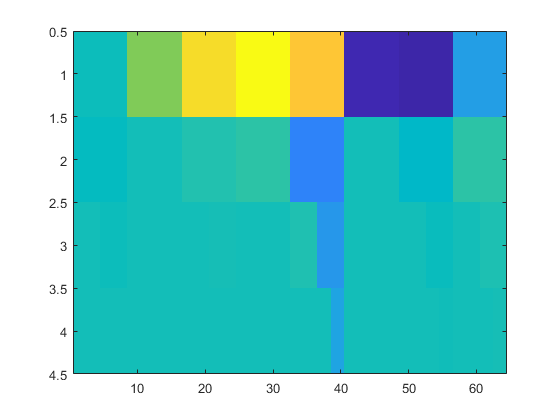

map1 = waveletDecompositionMap(c1,3,length(s1));
imagesc(map1)

e)** Repeat b) and c) for lab5 dataset2.mat.**

load('dataset2.mat')
s2 = s

s2 = 	1.0e+03 *

    0.9597    0.9594    0.9592    0.9590    0.9588    0.9586    0.9585    0.9583    0.9582    0.9581    0.9580    0.9579    0.9578    0.9578    0.9577    0.9577    0.9578    0.9580    0.9583    0.9586    0.9592    0.9599    0.9609    0.9620    0.9633    0.9647    0.9661    0.9676    0.9691    0.9704    0.9717    0.9728    0.9738    0.9747    0.9756    0.9762    0.9768    0.9773    0.9775    0.9776    0.9775    0.9771    0.9764    0.9755    0.9745    0.9733    0.9722    0.9713    0.9707    0.9702


[h3,g3] = dbfilter(2);
[a1,d1] = discreteWaveletTransformCausal(s2,h3,g3);
s2_out = discreteWaveletreconstruction(a1,d1,h3,g3)

s2_out = 	1.0e+03 *

    0.6554    1.1351    0.9592    0.9590    0.9588    0.9586    0.9585    0.9583    0.9582    0.9581    0.9580    0.9579    0.9578    0.9578    0.9577    0.9577    0.9578    0.9580    0.9583    0.9586    0.9592    0.9599    0.9609    0.9620    0.9633    0.9647    0.9661    0.9676    0.9691    0.9704    0.9717    0.9728    0.9738    0.9747    0.9756    0.9762    0.9768    0.9773    0.9775    0.9776    0.9775    0.9771    0.9764    0.9755    0.9745    0.9733    0.9722    0.9713    0.9707    0.9702


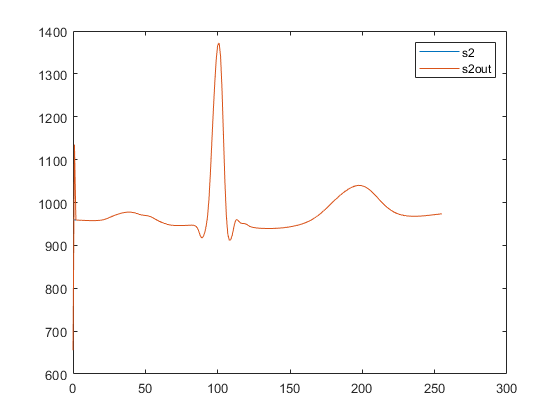

x_s2 = (0:length(s2)-1);
plot(x_s2,s2)
hold on
plot(x_s2,s2_out)
hold off
legend('s2','s2out')

c2 = wldecom_Db(s2,3,2);

h =    -0.0915    0.1585    0.5915    0.3415


g =    -0.3415    0.5915   -0.1585   -0.0915


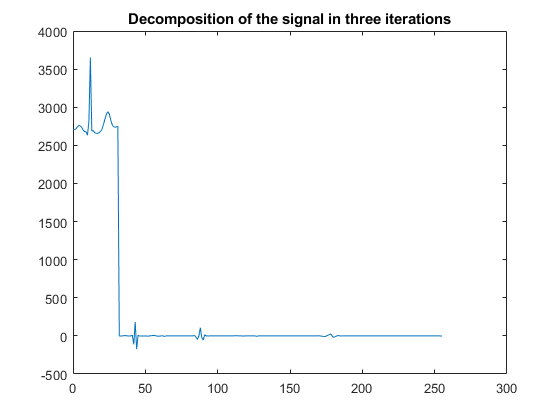

x_c2 = (0:length(c2)-1);
plot(x_c2,c2)
title("Decomposition of the signal in three iterations")

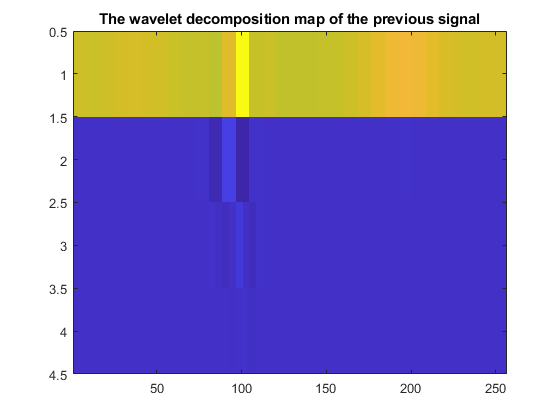

map2 = waveletDecompositionMap(c2,3,length(s2));
imagesc(map2)
title("The wavelet decomposition map of the previous signal")

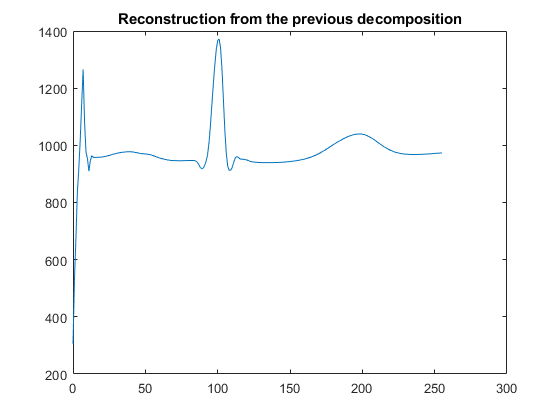

c2_rec = wlrecon_Db(c2,3,2);
x_c2rec = (0:length(c2_rec)-1);
plot(x_c2rec,c2_rec)
title("Reconstruction from the previous decomposition")

**EXERCICE 3**

**2D Daubechies Wavelet Transforms**

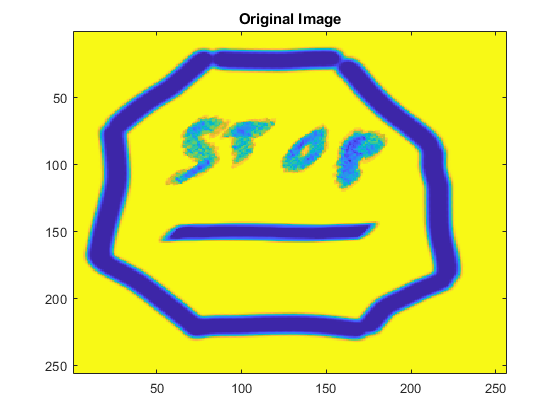

load('lab5_dataset3.mat')
s3 = s;
image(s3)
title('Original Image')

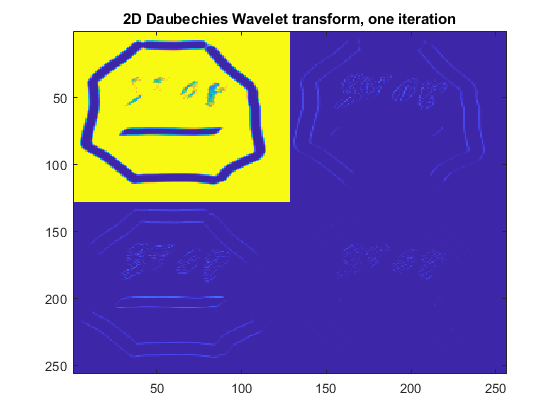

[B,H,V,D] = dwlt2_Daubechies(s3,2);
image([B V;H D])
title('2D Daubechies Wavelet transform, one iteration')

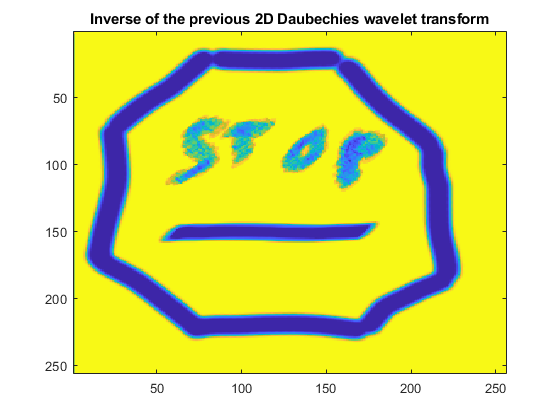

s2_r = idwlt2_Daubechies(B,H,V,D,2);
image(s2_r)
title('Inverse of the previous 2D Daubechies wavelet transform')

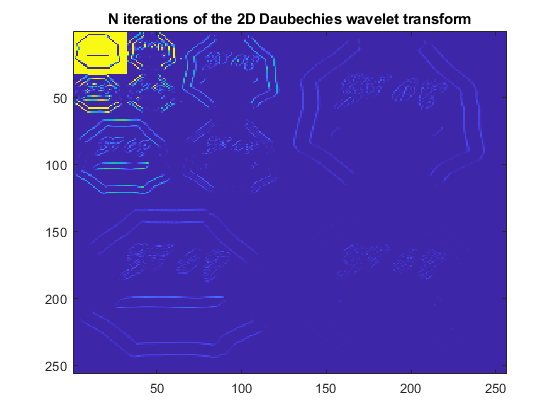

%At each iteration we only take B and repass through Daubechies transform and
% just add this to the image in the new quadrant
N=3;
B = s3;
for i = 1:N
    [B,H,V,D] = dwlt2_Daubechies(B,2);
    Im(1:size(B,1)+size(V,1),1:size(B,2)+size(H,1)) = [B V;H D];
end

image(Im)
title('N iterations of the 2D Daubechies wavelet transform')